# FID-A Data Processing Sandbox

*Georg Oeltzschner, 2021.*

Welcome to this MATLAB live script! This workbook has been written to introduce you to a couple of basic processing functionalities of the FID-A toolbox, a modular set of methods and structures for simulating and analyzing MRS data in MATLAB.

FID-A functions form the backbone of the Osprey software, so we will start off with its building blocks, and then move on to a walkthrough on the Osprey workflow itself.

## Getting set up

If you haven't done so already, please clone [this entire repository](https://github.com/schorschinho/pregame-workshop-2021) into a folder of your choice on your computer. Osprey contains a modified (and slightly limited) sub-collection of the original FID-A repository, so before you get started, please remove any other FID-A instances that you might have included in your MATLAB path, as they may otherwise shadow each other.

For further detail on getting Osprey completely set up on your computer, please follow the steps outlined in the [Osprey documentation](https://schorschinho.github.io/osprey/getting-started.html#installing-osprey).

### System requirements

We have tested this live script using MATLAB version 2019b on MacOS Catalina and Big Sur.

% Clear the workspace
clear;

% Add path to the data
pathData = fullfile(pwd, 'pregame-workshop-2021');
addpath(genpath(pathData));

% Add Osprey path
pathOsprey = fullfile(pwd, 'osprey');
addpath(genpath(pathOsprey));

## Modular processing with FID-A

### Input/output functions

When you look in the sub-folder `osprey/libraries/FID-A/inputOutput`, you will find a plethora of read and write functions. We will use on of these functions for NIfTI-MRS data (`io_loadspec_niimrs`) to load some example data from the Osprey folder, and play around a little:

% Point to an example pair of datasets
metDataFile = fullfile(pwd, 'osprey', 'exampledata', 'nifti-mrs', 'sub-01', 'ses-01', 'mrs', 'sub-01_ses-01_SVS.nii.gz');
refDataFile = fullfile(pwd, 'osprey', 'exampledata', 'nifti-mrs', 'sub-01', 'ses-01', 'mrs', 'sub-01_ses-01_SVS-ref.nii.gz');

% Load our data
metData = io_loadspec_niimrs(metDataFile);
refData = io_loadspec_niimrs(refDataFile);

### The FID-A structure

metData

metData = struct with fields:
          nucleus: {'1H'}
             fids: [2048×32×64 double]
            specs: [2048×32×64 double]
               sz: [2048 32 64]
             dims: [1×1 struct]
               Bo: 6.9808
         averages: 64
      rawAverages: 64
         subspecs: 1
      rawSubspecs: 1
               te: 0.0110
               tr: 5
                t: [1×2048 double]
              ppm: [1×2048 double]
       centerFreq: 4.6500
    spectralwidth: 6.0024e+03
        dwelltime: 1.6660e-04
            txfrq: 297219948
          nii_mrs: [1×1 struct]
              seq: 'svs_st'
         geometry: [1×1 struct]
            flags: [1×1 struct]


We can inspect the FID-A structure. As you heard in the introduction talk on Tuesday, the FID-A structure represents an MRS dataset completely, in an almost object-oriented way - the field `fids` and `specs` contain the frequency- and time-domain data, the field `dims` the dimension usage, `geometry` the voxel dimensions and orientation, etc. 

Let's visualize the frequency domain signals by using the `op_plotspec` command, which will prompt us to decide which dimension of the data we want to display - this dataset has multiple coils and multiple averages, which we can't all display at the same time! Enter your preference when prompted.

More than 1 dimension detected in addition to the frequency dimension.
Which dimension would you like to be displayed? 
     Enter: '2' to display signal from all RF channels.
     Enter: '3' to display signal from all averages.


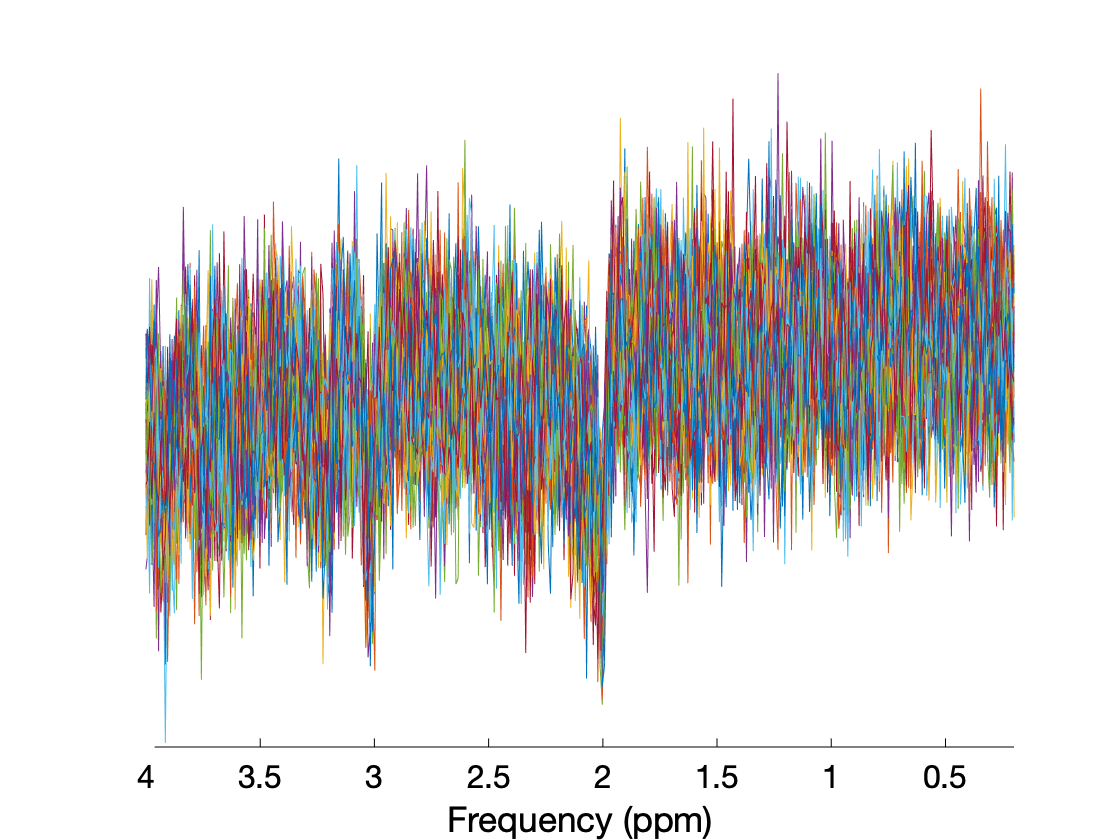

% Plot
ppmMetRange = [0.2 4]; % ppm plot range
fig1 = op_plotspec(metData, 0, 0, 0, 0, '', ppmMetRange(1), ppmMetRange(2));

### Combining coils

Let's first get rid of the coil dimension. Fortunately, FID-A does most of this for us automatically in two functions:

% Estimate optimal coil-combination coefficients and phases from the water
% reference data
% '1' - we're using the first point of the time-domain signal
% 'h' - we're using the Hall method to determine optimal weighting (S/N^2)
coeffs = op_getcoilcombos(refData, 1, 'h');

% Apply coil-combination coefficients to the metabolite and the water
% reference data
metDataComb = op_addrcvrs(metData, 1, 'h', coeffs);
refDataComb = op_addrcvrs(refData, 1, 'h', coeffs);

Now, we can look at the data again:

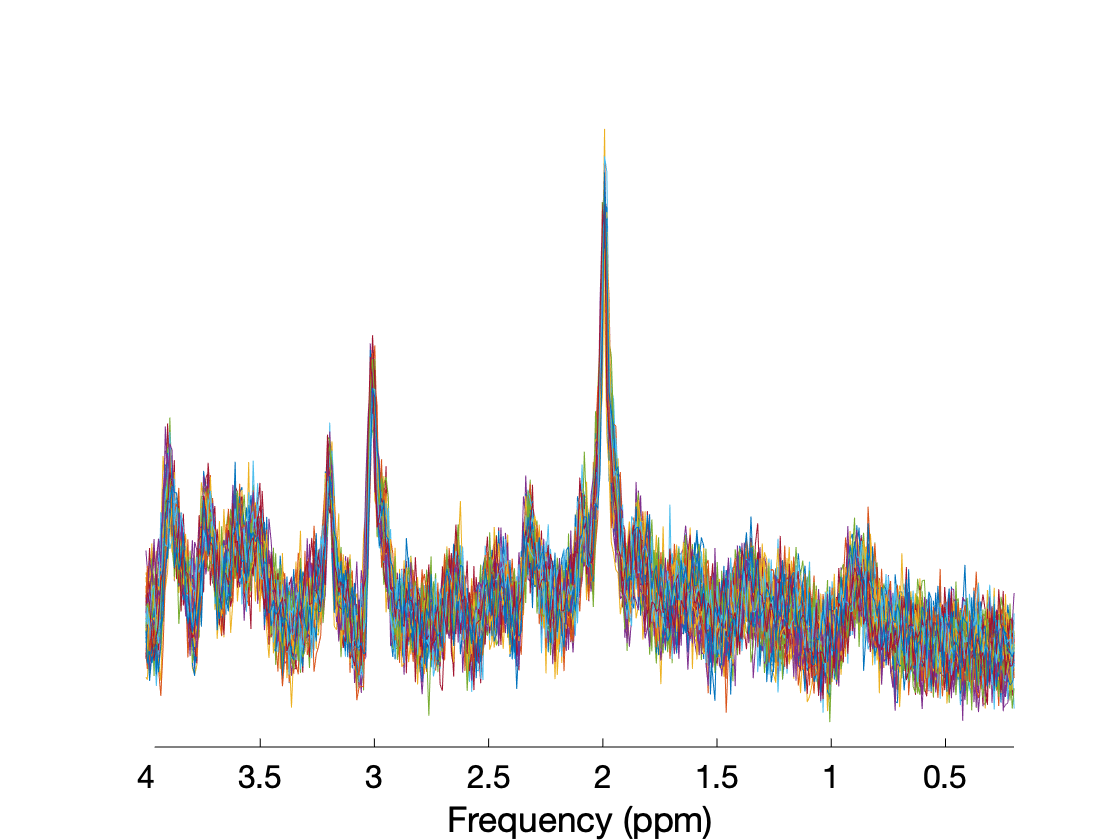

ppmMetRange = [0.2 4]; % ppm plot range
fig2 = op_plotspec(metDataComb, 0, 0, 0, 0, '', ppmMetRange(1), ppmMetRange(2));

### Aligning averages

In the next step, we'll perform spectral registration to align our individual averages using a built-in FID-A function `op_alignAverages`

% Align metabolite data
metDataAlign = op_alignAverages(metDataComb);

med = 'n'

tmax not supplied.  Calculating tmax....
tmax = 36.0689ms.


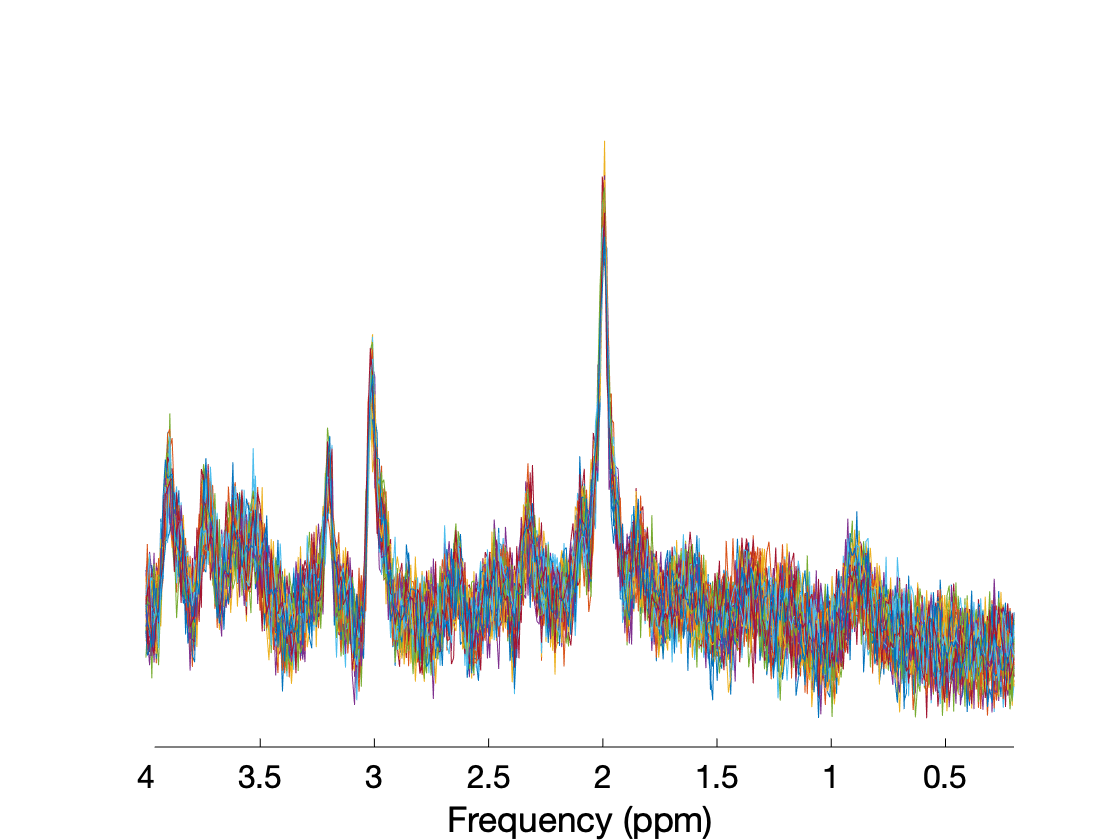

fig3 = op_plotspec(metDataAlign, 0, 0, 0, 0, '', ppmMetRange(1), ppmMetRange(2));

### Averaging

Now we're left with the most simple task: averaging across the aligned spectra!

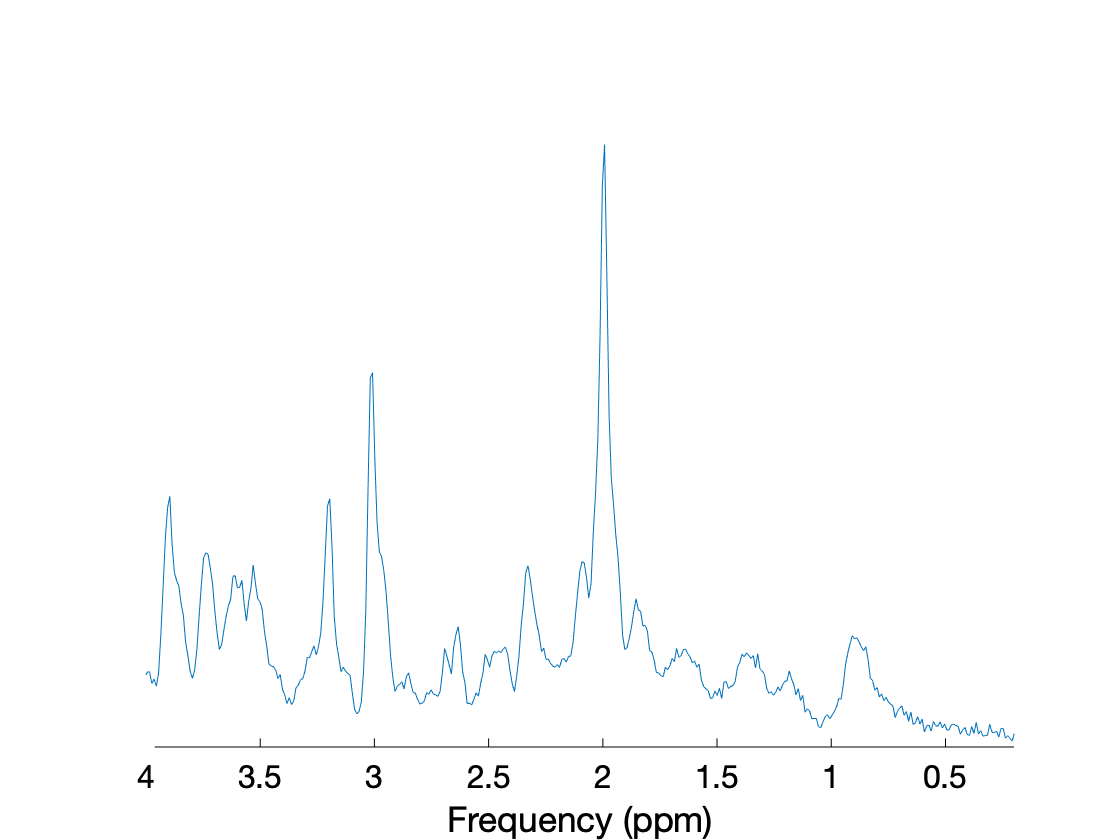

metDataAvgd = op_averaging(metDataAlign);
fig3 = op_plotspec(metDataAvgd, 0, 0, 0, 0, '', ppmMetRange(1), ppmMetRange(2));

## Sandbox time!

Explore the FID-A functions in the `osprey/libraries/FID-A` folder a little bit. See whether you can accomplish the following tasks (separately, not in order), and visualize the outcome of each step:

- Shift the entire spectrum by 0.2 ppm towards water

- Apply a zero-order phase of +76 degrees.

- Cut out a spectral region between -2 and 5 ppm.

- Remove the residual water peak from the metabolite data.

- Scale the spectrum by a factor of 1000.

- Perform eddy-current correction.